# Generating cost

## Import the data

### Import DAM LBMP data in 2019

clear;
% Import hourly DAM LBMP data in Jan 2019
priceFileDir = "D:\EERL\ny_academic_model\data\2019_DAM_LBMP_Generator\";
priceFileName = '2019*damlbmp_gen.csv';
DAMPriceDataShoreJan = fileDatastore(priceFileDir + priceFileName, "ReadFcn", @importDAMPriceData, "UniformRead", true);
priceAll = readall(DAMPriceDataShoreJan);
clear DAMPriceDataShoreJan;

% Format datetime to match the generation dataset
priceAll.Date = dateshift(priceAll.TimeStamp, 'start', 'day');
priceAll.Hour = priceAll.TimeStamp.Hour

priceAll = 4877764×8 table
       TimeStamp             NYISOname           PTID     LBMPMWHr    MarginalCostLossesMWHr    MarginalCostCongestionMWHr          Date          Hour
    ________________    ____________________    ______    ________    ______________________    __________________________    ________________    ____

    01/01/2019 00:00    59TH STREET_GT_1        24138      25.73               0.99                        -14.4              01/01/2019 00:00     0  
    01/01/2019 00:00    74TH STREET_GT_1        24260      25.48               1.01                       -14.12              01/01/2019 00:00     0  
    01/01/2019 00:00    74TH STREET_GT_2        24261      25.48               1.01             

### Import generation data in 2019

genFileDir = "D:\EERL\ny_academic_model\data\EPA_AMPD\2019\";
genFileName = "emission*.csv";
generationDataStore = fileDatastore(genFileDir + genFileName, "ReadFcn", @importGenerationData, "UniformRead", true);
genAll = readall(generationDataStore);
clear generationDataStore

### Import RGGI to NYCA reference table

% Import the reference table from RGGI to NYISO NYCA database
RGGI2NYCA2019 = importRGGI2NYCA("D:\EERL\ny_academic_model\data\EPA_AMPD\RGGI_2_NYCA_2019.xlsx");
generatorCombiner = RGGI2NYCA2019(:, ["NYISOname", "PTID", "FacilityName", "FacilityID", "UnitID", "NYAMUnit", "Region", "UnitType", "FuelType", "NamePlateRatingMW"]);
% Exclude generators that are not included in NYAM units
generatorCombiner = generatorCombiner(generatorCombiner.NYAMUnit ~= 'NA',:);
% Exclude generators fueling on wood and refuse (renewable energy)
generatorCombiner = generatorCombiner(generatorCombiner.FuelType ~= "Wood" & generatorCombiner.FuelType ~= "Refuse", :);
% Remove unused categories
generatorCombiner.NYISOname = removecats(generatorCombiner.NYISOname);
generatorCombiner.PTID = removecats(generatorCombiner.PTID);
generatorCombiner.FacilityName = removecats(generatorCombiner.FacilityName);
generatorCombiner.FacilityID = removecats(generatorCombiner.FacilityID);
generatorCombiner.UnitID = removecats(generatorCombiner.UnitID);
generatorCombiner.NYAMUnit = removecats(generatorCombiner.NYAMUnit);
generatorCombiner.Region = removecats(generatorCombiner.Region);
generatorCombiner.UnitType = removecats(generatorCombiner.UnitType);
generatorCombiner.FuelType = removecats(generatorCombiner.FuelType);

## Combine data tables

### Combine the generation data with the reference table

% Join tables generation data with the reference table
jiontGenAll = outerjoin(genAll,generatorCombiner,'Type', 'right', 'Keys',{'FacilityName','FacilityID','UnitID'},...
    "LeftVariables", {'Date', 'Hour', 'GrossLoadMW', 'OperatingTime', 'HeatInputMMBtu'}, "RightVariables", ...
    {'NYISOname', 'PTID', 'FacilityName', 'FacilityID', 'NYAMUnit', 'Region', 'UnitType', 'FuelType', 'NamePlateRatingMW'})

jiontGenAll = 1454160×14 table
       Date       Hour    GrossLoadMW    OperatingTime    HeatInputMMBtu    NYISOname    PTID     FacilityName    FacilityID    NYAMUnit    Region         UnitType          FuelType      NamePlateRatingMW
    __________    ____    ___________    _____________    ______________    _________    _____    ____________    __________    ________    ______    __________________    ___________    _________________

    01/01/2019      0          0               0                0           Gowanu

### Combine the joint generation data with price data

% Join tables
GenPriceAll = outerjoin(jiontGenAll,priceAll,'Type','left','Keys',{'Date','Hour','PTID'},'MergeKeys',true, ...
    "LeftVariables", {'Date', 'Hour', 'NYISOname', 'PTID', 'NYAMUnit', 'Region', 'UnitType', 'FuelType', 'GrossLoadMW', 'HeatInputMMBtu', 'NamePlateRatingMW', 'OperatingTime'}, ...
    "RightVariables", {'LBMPMWHr', 'MarginalCostCongestionMWHr', 'MarginalCostLossesMWHr'});

GenPriceAll = 1454318×16 table
       Date       Hour        NYISOname         PTID     NYAMUnit    Region         UnitType          FuelType      GrossLoadMW    HeatInputMMBtu    NamePlateRatingMW    OperatingTime    LBMPMWHr    MarginalCostCongestionMWHr    MarginalCostLossesMWHr    Dayofyear
    __________    ____    __________________    _____    ________    ______    __________________    ___________    ___________    ______________    _________________    _____________    ________    ____

GenPriceAll.Dayofyear = day(GenPriceAll.Date, 'dayofyear');

## Subset data table with NYAM units

% Subset the generator summary table by NYAM units
GenPriceA2FCC = GenPriceAll(GenPriceAll.NYAMUnit == "A2F-CC", :);
GenPriceA2FST = GenPriceAll(GenPriceAll.NYAMUnit == "A2F-ST", :);
GenPriceGHIST = GenPriceAll(GenPriceAll.NYAMUnit == "GHI-ST", :);
GenPriceJCC = GenPriceAll(GenPriceAll.NYAMUnit == "J-CC", :);
GenPriceJCT = GenPriceAll(GenPriceAll.NYAMUnit == "J-CT", :);
GenPriceJST = GenPriceAll(GenPriceAll.NYAMUnit == "J-ST", :);
GenPriceKCT = GenPriceAll(GenPriceAll.NYAMUnit == "K-CT", :);
GenPriceKST = GenPriceAll(GenPriceAll.NYAMUnit == "K-ST", :);

## Plot generation and price of all generators (no aggregation)

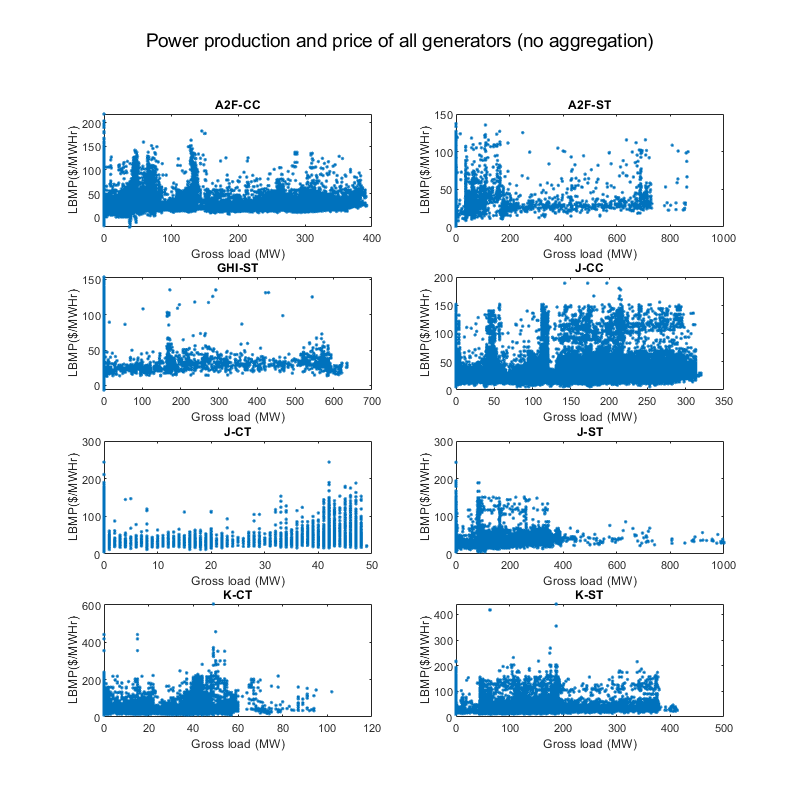

figure;
subplot(4,2,1);
scatter(GenPriceA2FCC.GrossLoadMW, GenPriceA2FCC.LBMPMWHr, ".");
title("A2F-CC"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,2);
scatter(GenPriceA2FST.GrossLoadMW, GenPriceA2FST.LBMPMWHr, ".");
title("A2F-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,3);
scatter(GenPriceGHIST.GrossLoadMW, GenPriceGHIST.LBMPMWHr, ".");
title("GHI-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,4);
scatter(GenPriceJCC.GrossLoadMW, GenPriceJCC.LBMPMWHr, ".");
title("J-CC"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,5);
scatter(GenPriceJCT.GrossLoadMW, GenPriceJCT.LBMPMWHr, ".");
title("J-CT"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,6);
scatter(GenPriceJST.GrossLoadMW, GenPriceJST.LBMPMWHr, ".");
title("J-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,7);
scatter(GenPriceKCT.GrossLoadMW, GenPriceKCT.LBMPMWHr, ".");
title("K-CT"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,8);
scatter(GenPriceKST.GrossLoadMW, GenPriceKST.LBMPMWHr, ".");
title("K-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
suptitle("Power production and price of all generators (no aggregation)");
set(gcf, 'Units', 'Pixels', 'Position', [100, 100, 800, 800]);

## Summarize power generation and price data grouped by NYAM units

sumGenPriceA2FCC = groupsummary(GenPriceA2FCC, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "LBMPMWHr", "MarginalCostCongestionMWHr", "MarginalCostLossesMWHr"]);
sumGenPriceA2FST = groupsummary(GenPriceA2FST, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "LBMPMWHr", "MarginalCostCongestionMWHr", "MarginalCostLossesMWHr"]);
sumGenPriceGHIST = groupsummary(GenPriceGHIST, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "LBMPMWHr", "MarginalCostCongestionMWHr", "MarginalCostLossesMWHr"]);
sumGenPriceJCC = groupsummary(GenPriceJCC, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "LBMPMWHr", "MarginalCostCongestionMWHr", "MarginalCostLossesMWHr"]);
sumGenPriceJCT = groupsummary(GenPriceJCT, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "LBMPMWHr", "MarginalCostCongestionMWHr", "MarginalCostLossesMWHr"]);
sumGenPriceJST = groupsummary(GenPriceJST, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "LBMPMWHr", "MarginalCostCongestionMWHr", "MarginalCostLossesMWHr"]);
sumGenPriceKCT = groupsummary(GenPriceKCT, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "LBMPMWHr", "MarginalCostCongestionMWHr", "MarginalCostLossesMWHr"]);
sumGenPriceKST = groupsummary(GenPriceKST, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "LBMPMWHr", "MarginalCostCongestionMWHr", "MarginalCostLossesMWHr"]);

sumGenPriceA2FCC = removeRepeat1103(sumGenPriceA2FCC);
sumGenPriceA2FST = removeRepeat1103(sumGenPriceA2FST);
sumGenPriceGHIST = removeRepeat1103(sumGenPriceGHIST);
sumGenPriceJCC = removeRepeat1103(sumGenPriceJCC);
sumGenPriceJCT = removeRepeat1103(sumGenPriceJCT);
sumGenPriceJST = removeRepeat1103(sumGenPriceJST);
sumGenPriceKCT = removeRepeat1103(sumGenPriceKCT);
sumGenPriceKST = removeRepeat1103(sumGenPriceKST);

## Plot total generation and total price of aggregated NYAM units

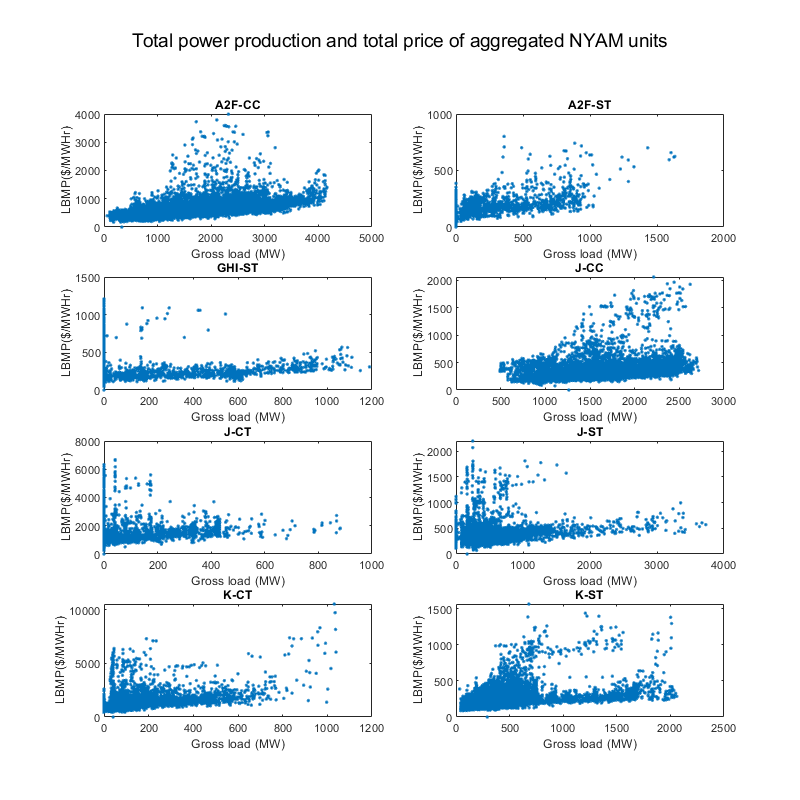

figure;
subplot(4,2,1);
scatter(sumGenPriceA2FCC.sum_GrossLoadMW, sumGenPriceA2FCC.sum_LBMPMWHr, ".");
title("A2F-CC"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,2);
scatter(sumGenPriceA2FST.sum_GrossLoadMW, sumGenPriceA2FST.sum_LBMPMWHr, ".");
title("A2F-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,3);
scatter(sumGenPriceGHIST.sum_GrossLoadMW, sumGenPriceGHIST.sum_LBMPMWHr, ".");
title("GHI-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,4);
scatter(sumGenPriceJCC.sum_GrossLoadMW, sumGenPriceJCC.sum_LBMPMWHr, ".");
title("J-CC"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,5);
scatter(sumGenPriceJCT.sum_GrossLoadMW, sumGenPriceJCT.sum_LBMPMWHr, ".");
title("J-CT"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,6);
scatter(sumGenPriceJST.sum_GrossLoadMW, sumGenPriceJST.sum_LBMPMWHr, ".");
title("J-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,7);
scatter(sumGenPriceKCT.sum_GrossLoadMW, sumGenPriceKCT.sum_LBMPMWHr, ".");
title("K-CT"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,8);
scatter(sumGenPriceKST.sum_GrossLoadMW, sumGenPriceKST.sum_LBMPMWHr, ".");
title("K-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
suptitle("Total power production and total price of aggregated NYAM units");
set(gcf, 'Units', 'Pixels', 'Position', [100, 100, 800, 800]);

## Fit quadratic function of total price and total production of NYAM units

polyGenPriceA2FCC = polyfit(sumGenPriceA2FCC.sum_GrossLoadMW, sumGenPriceA2FCC.sum_LBMPMWHr, 2);
polyGenPriceA2FST = polyfit(sumGenPriceA2FST.sum_GrossLoadMW, sumGenPriceA2FST.sum_LBMPMWHr, 2);
polyGenPriceGHIST = polyfit(sumGenPriceGHIST.sum_GrossLoadMW, sumGenPriceGHIST.sum_LBMPMWHr, 2);
polyGenPriceJCC = polyfit(sumGenPriceJCC.sum_GrossLoadMW, sumGenPriceJCC.sum_LBMPMWHr, 2);
polyGenPriceJCT = polyfit(sumGenPriceJCT.sum_GrossLoadMW, sumGenPriceJCT.sum_LBMPMWHr, 2);
polyGenPriceJST = polyfit(sumGenPriceJST.sum_GrossLoadMW, sumGenPriceJST.sum_LBMPMWHr, 2);
polyGenPriceKCT = polyfit(sumGenPriceKCT.sum_GrossLoadMW, sumGenPriceKCT.sum_LBMPMWHr, 2);
polyGenPriceKST = polyfit(sumGenPriceKST.sum_GrossLoadMW, sumGenPriceKST.sum_LBMPMWHr, 2);

## Plot the fitted quadratic function and the original data

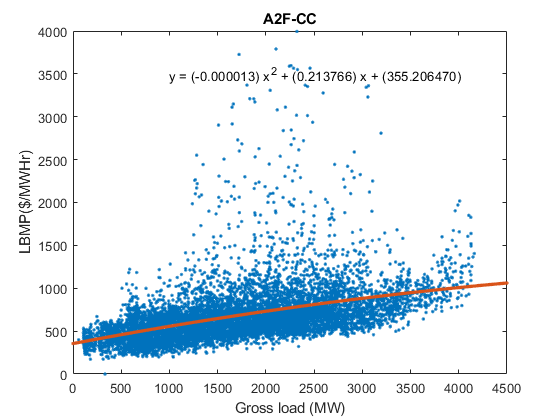

figure;
scatter(sumGenPriceA2FCC.sum_GrossLoadMW, sumGenPriceA2FCC.sum_LBMPMWHr, ".");
title("A2F-CC"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)");
hold on;
x = [0:4500]';
predGenPriceA2FCC = polyval(polyGenPriceA2FCC, x);
scatter(x, predGenPriceA2FCC, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceA2FCC(1), polyGenPriceA2FCC(2), polyGenPriceA2FCC(3));
text(1000, 3500, s);
hold off; box on;

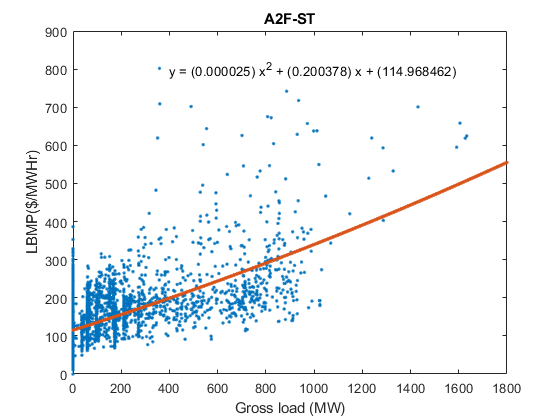

figure;
scatter(sumGenPriceA2FST.sum_GrossLoadMW, sumGenPriceA2FST.sum_LBMPMWHr, ".");
title("A2F-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)");
hold on;
x = [0:1800]';
predGenPriceA2FST = polyval(polyGenPriceA2FST, x);
scatter(x, predGenPriceA2FST, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceA2FST(1), polyGenPriceA2FST(2), polyGenPriceA2FST(3));
text(400, 800, s);
hold off; box on;

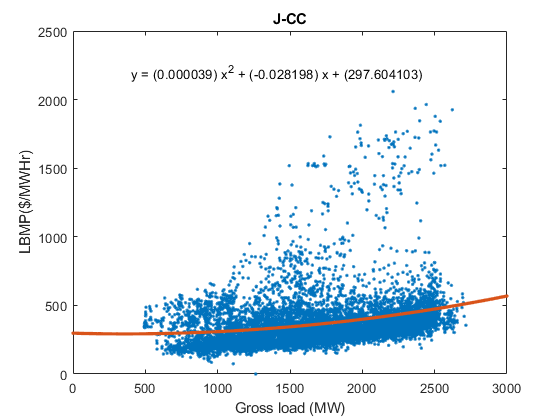

figure;
scatter(sumGenPriceJCC.sum_GrossLoadMW, sumGenPriceJCC.sum_LBMPMWHr, ".");
title("J-CC"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)");
hold on;
x = [0:3000]';
predGenPriceJCC = polyval(polyGenPriceJCC, x);
scatter(x, predGenPriceJCC, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceJCC(1), polyGenPriceJCC(2), polyGenPriceJCC(3));
text(400, 2200, s);
hold off; box on;

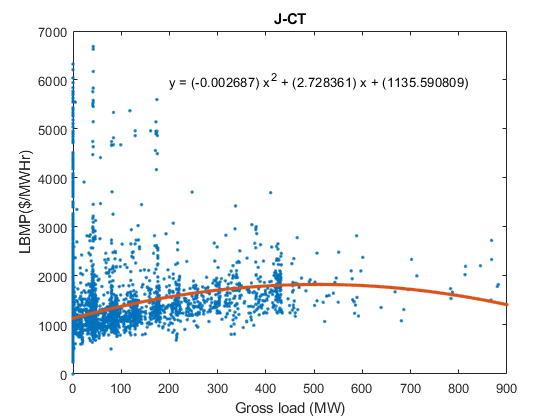

figure;
scatter(sumGenPriceJCT.sum_GrossLoadMW, sumGenPriceJCT.sum_LBMPMWHr, ".");
title("J-CT"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)");
hold on;
x = [0:900]';
predGenPriceJCT = polyval(polyGenPriceJCT, x);
scatter(x, predGenPriceJCT, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceJCT(1), polyGenPriceJCT(2), polyGenPriceJCT(3));
text(200, 6000, s);
hold off; box on;

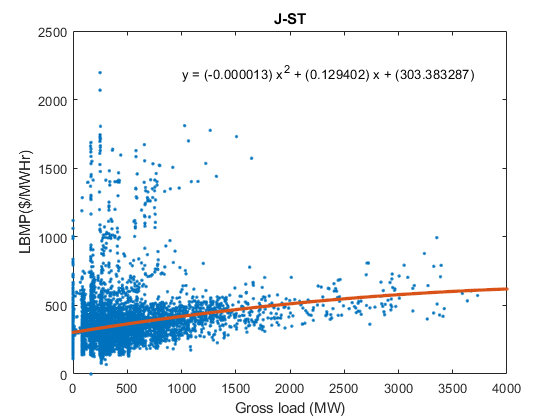

figure;
scatter(sumGenPriceJST.sum_GrossLoadMW, sumGenPriceJST.sum_LBMPMWHr, ".");
title("J-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)");
hold on;
x = [0:4000]';
predGenPriceJST = polyval(polyGenPriceJST, x);
scatter(x, predGenPriceJST, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceJST(1), polyGenPriceJST(2), polyGenPriceJST(3));
text(1000, 2200, s);
hold off; box on;

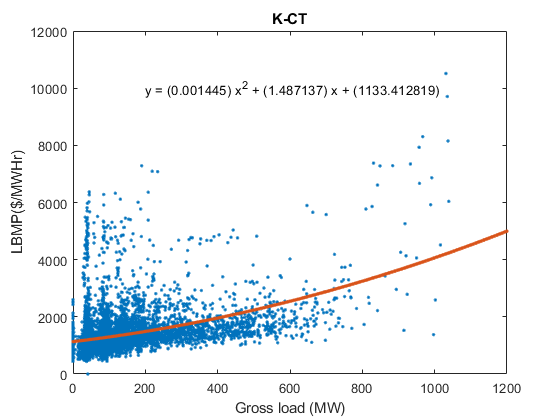

figure;
scatter(sumGenPriceKCT.sum_GrossLoadMW, sumGenPriceKCT.sum_LBMPMWHr, ".");
title("K-CT"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)");
hold on;
x = [0:1200]';
predGenPriceKCT = polyval(polyGenPriceKCT, x);
scatter(x, predGenPriceKCT, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceKCT(1), polyGenPriceKCT(2), polyGenPriceKCT(3));
text(200, 10000, s);
hold off; box on;

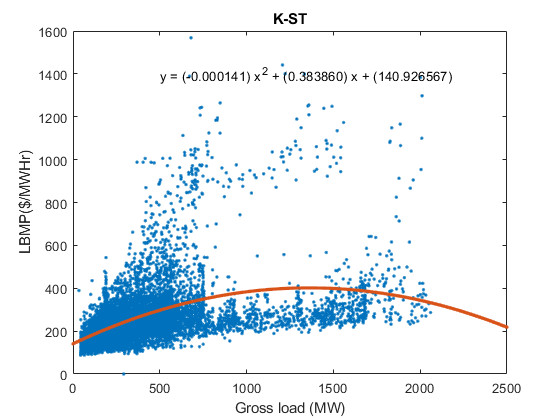

figure;
scatter(sumGenPriceKST.sum_GrossLoadMW, sumGenPriceKST.sum_LBMPMWHr, ".");
title("K-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)");
hold on;
x = [0:2500]';
predGenPriceKST = polyval(polyGenPriceKST, x);
scatter(x, predGenPriceKST, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceKST(1), polyGenPriceKST(2), polyGenPriceKST(3));
text(500, 1400, s);
hold off; box on;

sumGenPriceA2FCC.LBMPRate = sumGenPriceA2FCC.sum_LBMPMWHr./sumGenPriceA2FCC.sum_GrossLoadMW

sumGenPriceA2FCC = 8760×10 table
       Date       Hour    GroupCount    sum_GrossLoadMW    sum_HeatInputMMBtu    sum_LBMPMWHr    sum_MarginalCostCongestionMWHr    sum_MarginalCostLossesMWHr    Dayofyear    LBMPRate
    __________    ____    __________    _______________    __________________    ____________    ______________________________    __________________________    _________    ________

    01/01/2019      0         37              208                1913.2             472.24                   -169.3                           3.16                   1         2.2704 
    01/01/2019      1         37              116                  1329      

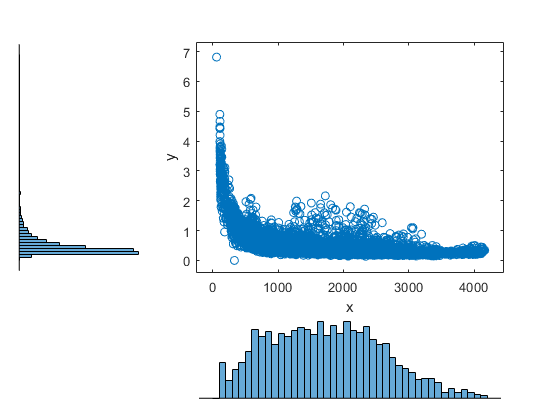

scatterhist(sumGenPriceA2FCC.sum_GrossLoadMW, sumGenPriceA2FCC.LBMPRate)